% get commit list
start_date = '2024-11-25';
git_cmd = strcat("git rev-list --pretty=%h%ad --date=short --since=", start_date, " HEAD");
[~, commit_list_str] = system(git_cmd);
commit_list_cell = splitlines(commit_list_str);
commit_list_cell = commit_list_cell(2:2:end-1);

hash_cell = cellfun(@(s) s(1:min(7, end)), commit_list_cell, 'UniformOutput', false);
date_cell = cellfun(@(s) s(8:end),         commit_list_cell, 'UniformOutput', false);

% make empty variables
power_report = nan(size(commit_list_cell));
power_wecsim = nan(size(commit_list_cell));

% Set your GitHub Personal Access Token (PAT) or use GitHub Action's GITHUB_TOKEN
GITHUB_TOKEN = fileread('github_token');

% Define options for the web request (including authentication header)
options = weboptions('HeaderFields', {'Authorization', ['token ' GITHUB_TOKEN]}, ...
                     'ContentType', 'json', 'Timeout', 30);

repo_url = 'https://api.github.com/repos/symbiotic-engineering/MDOcean/';

N = length(commit_list_cell);


for idx_commit=1:N
    fprintf('Getting CI data for commit %d of %d\n', idx_commit, N)

    commit_sha = hash_cell{idx_commit};
    % Define the URL to fetch check runs
    url = [repo_url sprintf('commits/%s/check-runs', commit_sha)];
    
    % Send the GET request to GitHub API
    response = webread(url, options);
    
    % Parse the check runs from the response
    check_runs = response.check_runs;

    if ~isempty(check_runs)
        idx_junit = strcmp({check_runs.name},'JUnit Test Report');
        if any(idx_junit)
            id = num2str(check_runs(idx_junit).id);
        
            url_2 = [repo_url 'check-runs/' id '/annotations'];
            annotations = webread(url_2, options);
        
            if ~isempty(annotations)
                idx_report_power = contains({annotations.title},'report=power_avg');
                idx_wecsim_power = contains({annotations.title},'wecsim=power_avg');
            
                if any(idx_report_power)
                    power_report(idx_commit) = extract_actual_value(annotations(idx_report_power).raw_details);
                else
                    power_report(idx_commit) = 85.9;
                end
                if any(idx_wecsim_power)
                    power_wecsim(idx_commit) = extract_actual_value(annotations(idx_wecsim_power).raw_details);
                end
            end
        end
    end

end

Getting CI data for commit 1 of 379
Getting CI data for commit 2 of 379
Getting CI data for commit 3 of 379
Getting CI data for commit 4 of 379
Getting CI data for commit 5 of 379
Getting CI data for commit 6 of 379
Getting CI data for commit 7 of 379
Getting CI data for commit 8 of 379
Getting CI data for commit 9 of 379
Getting CI data for commit 10 of 379
Getting CI data for commit 11 of 379
Getting CI data for commit 12 of 379
Getting CI data for commit 13 of 379
Getting CI data for commit 14 of 379
Getting CI data for commit 15 of 379
Getting CI data for commit 16 of 379
Getting CI data for commit 17 of 379
Getting CI data for commit 18 of 379
Getting CI data for commit 19 of 379
Getting CI data for commit 20 of 379
Getting CI data for commit 21 of 379
Getting CI data for commit 22 of 379
Getting CI data for commit 23 of 379
Getting CI data for commit 24 of 379
Getting CI data for commit 25 of 379
Getting CI data for commit 26 of 379
Getting CI data for commit 27 of 379
Getting CI

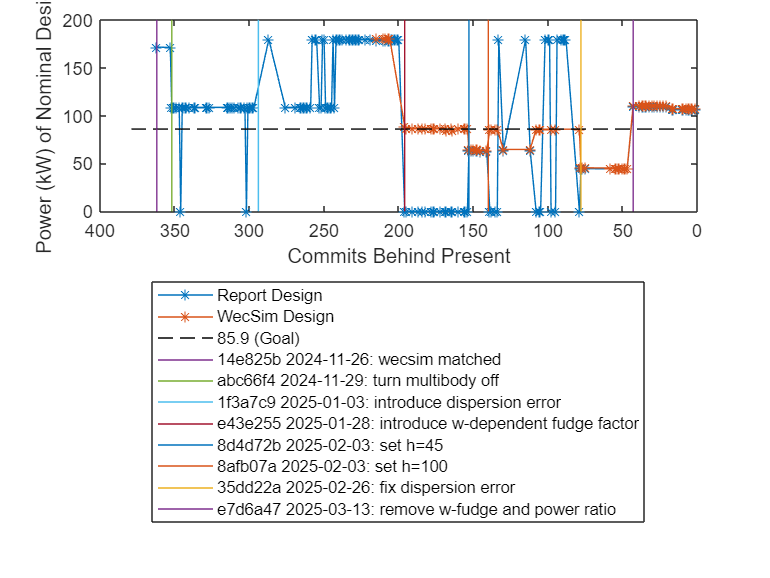


x = 1:N;

figure
plot(x(~isnan(power_report)), power_report(~isnan(power_report))/1000, '-*','DisplayName','Report Design')
hold on
plot(x(~isnan(power_wecsim)), power_wecsim(~isnan(power_wecsim))/1000, '-*','DisplayName','WecSim Design')
plot([1 N],85.9*[1 1],'k--','DisplayName','85.9 (Goal)')
xlabel('Commits Behind Present')
ylabel('Power (kW) of Nominal Design')
legend('location','southoutside')

set(gca, 'XDir','reverse')

% commits of interest
special.commits = {'35dd22a',          'e43e255',                           '1f3a7c9',                   'e7d6a47',                       '8d4d72b', '8afb07a',  'abc66f4',           '14e825b'};
special.note = {'fix dispersion error','introduce w-dependent fudge factor','introduce dispersion error','remove w-fudge and power ratio','set h=45','set h=100','turn multibody off','wecsim matched'};
[idx1,idx2] = ismember(hash_cell,special.commits);
tmp1 = find(idx1);
tmp2 = zeros(size(tmp1));
tmp2(idx2(idx2~=0)) = tmp1;
special.commit_idx = tmp2;

[~,sort_idx] = sort(special.commit_idx,'descend');
special_sorted = structfun(@(f) f(sort_idx), special, 'UniformOutput',false);

for i=1:length(special.commits)
    idx = special_sorted.commit_idx(i);
    day = date_cell{idx};
    name = [special_sorted.commits{i} ' ' day ': ' special_sorted.note{i}];
    plot([1 1]*idx, ylim,'DisplayName',name)
end


% turn drag on
% set power scale to 117/86


function value = extract_actual_value(annotation)
    capture_number = '([\d\.e\+-]+)';
    pattern = ['(?:Actual Value:\s*)' capture_number];
    matches = regexp(annotation, pattern, 'tokens');
    if ~isempty(matches)
        value = str2double(matches{1});
    else
        value = NaN;
    end
end